# Hands-On: Sampling Using an Ideal Sampler

## Introduction

Most system identification algorithms work on discrete-time data, which is obtained by sampling the continuous-time signals (inputs, outputs and/or state variables) of the physical system being modelled. 

In this Hands-On we focus on **periodic sampling: t**he continuous-time signal $v(t)$ is sampled at $t_k=k\,\Delta$, resulting in a discrete-time signal $v_d(k)$


$$v(t) \qquad \Longrightarrow \qquad t_{k} = k\, \Delta\,,\; k\in \mathbb{Z} \qquad \Longrightarrow \qquad \big\{ v_d(k): v_d(k) =v\left(k \Delta\right)\,,\; k\in \mathbb{Z}  \big\}$$


                              continuous-time signal          sampling time instants                    discrete-time signal

We analyse the impact of the sampling process and answer the following questions:

- What is the impact of sampling on the information in the sampled signals?

- What is the relation between the spectra of the continuous-time and discrete-time (sampled) signal?

- How to reduce the aliasing effect using an anti-alias filter? 

## Mathematical Formulation of the Sampling Process

### Time Domain

To link the continuous-time signal $x(t)$ and the discrete-time signal $x_d(k) = x(k\,\Delta)$, we define the intermediate continuous-time signal $x^{*}(t)$ by the product of the continuous-time signal $x(t) $ with a periodically repeated Dirac impulse $\delta_{\Delta}(t)=\sum_{k=-\infty}^{k=\infty}\delta(t-k\,\Delta)$, called also an **impulse train** (Phillips, C. L., Nagle, H. T., & Chakrabortty, A., 2015)


$$x^{*}(t)=x(t)\cdot \delta_{\Delta}(t)=\displaystyle \sum_{k=-\infty}^{k=\infty} x(k\,\Delta)\, \delta \left(t-k\,\Delta \right)$$


The continuous-time signal $x^*(t)$ is zero everywhere, excepted at the sampling times $k\,\Delta$ where it is a Dirac impulse multiplied with the value of the discrete-time signal $x_d(k) = x(k\, \Delta)$.

Remark: the impulse train and the signal $x^*(t)$ are mathematical abstractions requiring cautious mathematical treatment wich is outside the scope of this Hands-On (Phillips, Nagle, & Chakrabortty, 2015; Oppenheim, Shafer, & Buck, 1998).

#### Exercise: Illustrating the Sampling Process on a Sine

In the next exercise, we illustrate the impact of the sampling process. The continuous-time signal is $x(t) = sin \big(2\,\pi\, f\,t \big) \cdot 1(t)$ where $f$ is set by the reader. The signal is sampled with a sampling frequency $f_s=50$Hz. The results are shown in two figures.  In the top plot of the first figure, the continuous-time signal is shown in the time interval $[0,2]\, \text{s}$. The middle plot shows the Dirac impulse train, with impulses at $k\,\Delta = \frac{k}{f_s} = 0.02 \, k$. The bottom plot shows the discrete-time signal. In the second figure, the discrete-time signal is plotted (red dots) in overlay with the continuous-time signal (blue line).

- Set the frequency of the sine $f=1$Hz. Observe that the continuous-time signal can be retrieved from the discrete-time plot by *visual interpolating* the points.

- Increase the frequency to respectively $f=2, 3, 8$ Hz. Observe that for the highest frequency, the visual interpretation of the discrete-time signal becomes more difficult.

- Set $f=11$Hz. At first glance, we cannot see a sine signal. Zooming into the picture gives again a better visual representation of the original signal.

- Set $f=25$Hz, this is exactly half the sampling frequency $f_s=f/2$. The discrete-time points create two parallel lines. Check in the second figure that this is due to the alternate sampling of the same values of the continuous-time sine.

- Increase the frequency to $f=46$Hz. The visual interpolation of the discrete-time signal suggests a low frequency signal for the sampled signal with a frequency $|f-f_s|$Hz. Check at the second figure that this low frequency copy is obtained by slowly shifting through the fast continuous-time sine (only a few samples per period).

- Increase the frequency further on to respectively $f=48,\,49,\,50$ Hz. Observe that the apparent frequency of the discrete-time signal drops further towards $2,1,0$Hz.

- Increase the frequency again to $51$Hz. We retrieve again a low frequency copy at $|f-f_s|$ Hz. 

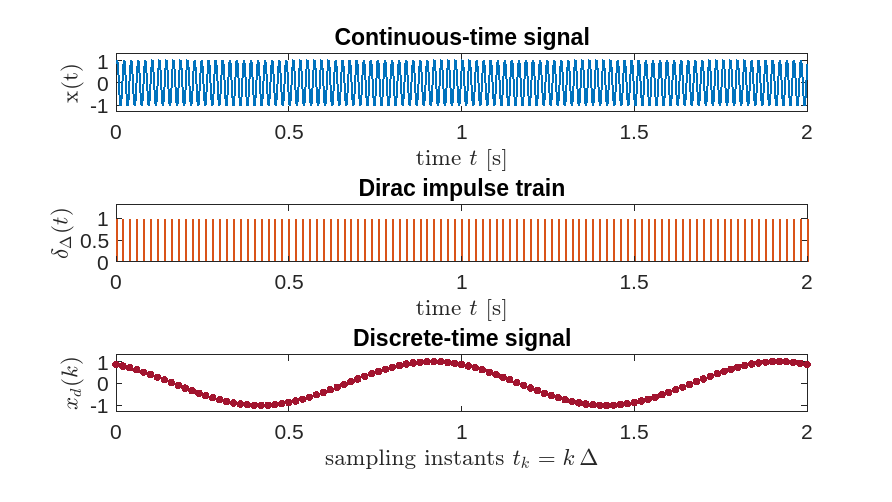

clear
 

colorset = myPlotColorSet;  % TThe function creates an array of RGB triplets, 
                            % defining the colors to use when drawing 
                            % 2D line plots. 
                            % Each row of "colorset" is an RGB triplet.

fs = 50;                    % sampling frequency [Hz]
nCT = 100;                  % oversampling factor (to plot the continuous-time signals as a smooth curve)
fsCT = fs*nCT;              % increased sampling frequency to plot the continuous-time signals
T = 2;                      % length of the interval to make the plots [s]
phi = pi/3;                 % set the phase of the continuous-time signal

% -- create signals to plot ---------------------------------------------
NDT = T*fs;                 % number of discrete-time points in interval - the effective samples
tDT = (0:NDT+1)*T/NDT;      % sampling time instants

NCT = T*fsCT;               % number of discrete-time points in interval 
                            % to plot the continuous-time signals as a smooth curve
tCT = (0:NCT+1)*T/NCT;      % the time instants used to evaluate and plot 
                            % the continuous-time signal as a smooth curve


f=49;  % set the frequency of the sine signal [Hz]


sinCT = sin(2*pi*f*tCT+phi);    % continuous-time signal plot
sinDT = sin(2*pi*f*tDT+phi);    % discrete-time signal plot
% -----------------------------------------------------------------------

% ------ plotting the continuous-time and the sampled-time signals ------
figure('Units','normalized', 'Position',[0.1, 0.1, 0.75, 0.75]);

% --- the continuous time signal x(t) -----
subplot(3,1,1);
plot(tCT,sinCT,'Color', colorset(1,:), 'LineStyle','-','LineWidth',1.5);
title('Continuous-time signal');
axis([0,2,-1.3,1.3]);
xlabel('time $t$ [s]','interpreter','latex'); ylabel('x(t)', 'Interpreter','latex');
set(gca, 'FontSize', 16);

% --- the Dirac impulse train ----------------
subplot(3,1,2);
stem(tDT,ones(size(tDT)),'Color',colorset(2,:) ,'LineWidth',1.5 , 'marker','none');
axis([0,2,0,1.3])
title('Dirac impulse train');
xlabel('time $t$ [s]','interpreter','latex'); 
ylabel('$\delta_{\Delta}(t)$', 'Interpreter','latex');
set(gca, 'FontSize', 16);

% --- the sampled signal x_d(k) --------------------
subplot(3,1,3)
plot(tDT,sinDT,'Color', colorset(7,:), ...
        'LineStyle','none','Marker','.','MarkerSize',14, 'MarkerFaceColor','auto');
axis([0,2,-1.3,1.3])
xlabel('sampling instants $t_{k} = k\,\Delta$','interpreter','latex'); 
ylabel('$x_{d}(k)$', 'Interpreter','latex');
title('Discrete-time signal');
set(gca, 'FontSize', 16);

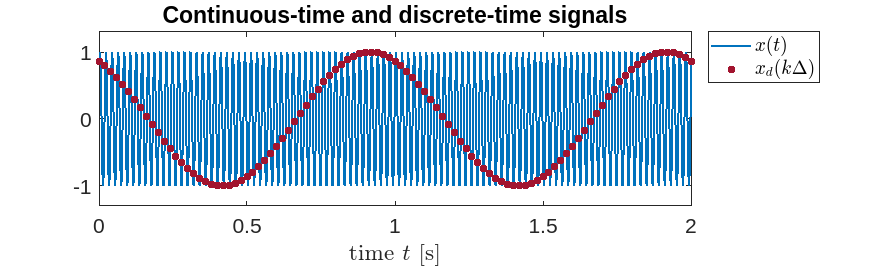


% ------ plotting the continuous-time and the sampled-time signals all toghether------
figure('Units','normalized', 'Position',[0.1, 0.1, 0.75, 0.40]);

plot(tCT,sinCT,'Color', colorset(1,:),'LineStyle','-', 'LineWidth', 1.5);
hold on;
plot(tDT,sinDT, 'Color', colorset(7,:),'LineStyle','none', 'Marker','.', ...
       'MarkerSize', 20, 'MarkerFaceColor','auto');
xlabel('time $t$ [s]','interpreter','latex');
title('Continuous-time and discrete-time signals')
axis([0,2,-1.3,1.3])
set(gca, 'FontSize', 16);
legend('$x(t)$', '$x_{d}(k \Delta)$', 'Location', 'bestoutside', 'Interpreter', 'latex')

#### **Conclusion**

A discrete-time signal $x_d(k)=x(k\,\Delta)$  is obtained by sampling the continuous-time signal $x(t)$.  If the sampling frequency $f_s=1/\Delta$ is much higher than the sine frequency $f$, the discrete-time signal seems to be a reliable copy of the original continuous-time signal. However, once the frequency becomes too high (for example close to $f_s/2$), the visual reconstruction of the original signal from the samples fails completely. And for even higher frequencies ($f \approx f_s$), we retrieve a slow sine at a frequency $|f-f_s|$ instead of the continuous-time fast varying sine. 

This raises the question if sampling is a reliable process to get a discrete-time representation of a continuous-time signal. More insight is needed to guarantee that the discrete-time signal can be used as a solid and sound basis for further calculations and conclusions. The theorem of Shannon provides a necessary and sufficient condition to guarantee that all information about the continuous-time signal can be retrieved from the samples of the discrete-time signal without using prior information of the original signal (besides knowing $f_{max}$). Shannon's theorem states that the sampling frequency should be larger than two times the maximum frequency that is present in the continuous-time signal: $f_s>2f_{max}$ (Oppenheim, Shafer, & Buck, 1998). This will be discussed later in detail in this Hands-On. First we need to understand what is going on in the frequency domain when a signal is sampled.

### Frequency Domain

To better understand the impact of the sampling process, we study the Fourier transforms of $x(t)$ and $x^*(t)$. 

Consider the **Fourier transform** $X(\Omega)=\mathcal{F}\left\{x(t) \right\}$ of $x(t)$

$X(\Omega) = X(2\pi f) =  \displaystyle \int_{-\infty}^{\infty} x(t)\,e^{-j2\pi ft}\, dt$.

For simplicity, we assume here and later in this Hands-On that this integral exists (no convergence problems related to the infinitely large integration interval). In this text, we will also use the notation $X(f)$ which is the Fourier transform $X(\Omega)$ that is evaluated at the frequency $f$ : $X(f) = \displaystyle X(\Omega) \vert_{\Omega = 2 \pi f}$.

The Dirac pulse train is periodic, so it is possible to describe it using a Fourier series:


$$\delta_{\Delta}(t) =   \displaystyle \sum_{k=-\infty}^{k=+\infty} \, C_{\Delta}(k) e^{jk\Omega_{\text{s}}t} \qquad \Omega_{\text{s}} = \frac{2\pi}{\Delta} $$


where


$$C_{\Delta}(k) = \displaystyle  \frac{1}{\Delta}\, \int_{-\frac{\Delta}{2}}^{+\frac{\Delta}{2}} \, \delta_{\Delta}(t) \,e^{-jk\Omega_{\text{s}}t} \, dt =  \frac{1}{\Delta}$$


Thus


$$\delta_{\Delta}(t) = \displaystyle  \frac{1}{\Delta} \, \sum_{k=-\infty}^{k=+\infty} \, e^{jk\Omega_{\text{s}}t}$$


By substitution of the impulse train expression into the ideal sampler output $x^{*}(t)$, we obtain


$$x^{*}(t) = x(t) \cdot \delta_{\Delta}(t)  = \displaystyle \frac{1}{\Delta} \, \sum_{k=-\infty}^{k=+\infty} \, x(t) \, e^{jk\Omega_{\text{s}}t}$$


Applying the Fourier transform:


$$X^{*}(\Omega) = \mathcal{F}\left\{ x^{*}(t)\right\} = \displaystyle  \frac{1}{\Delta} \, \sum_{k=-\infty}^{k=+\infty} \,  \int_{-\infty}^{+\infty} \, \left[  x(t) \, e^{jk\Omega_{\text{s}}}\right] e^{-j \Omega  t}\,dt $$


Recall the Fourier transform property


$$\mathcal{F} \big\{ e^{j\Omega_0} \cdot y(t) \big\} = Y \big( \Omega - \Omega_{0} \big) \, , \quad Y(\Omega) = \mathcal{F} \left\{ y(t) \right\}$$


Thus


$$X^{*}(\Omega) = \frac{1}{\Delta} \, \sum_{k=-\infty}^{k=+\infty} \, X\left( \Omega-k \Omega_{\text{s}} \right)   \, , \quad k \in \mathbb{Z}\,, \quad
	\Omega_{\text{s}} = \frac{2\pi}{\Delta}$$


or, equivalently 

$X^{*}(f) = f_{\text{s}} \, \displaystyle \sum_{k=-\infty}^{k=+\infty} \, X\left( f-k f_{\text{s}} \right)   \, , \quad k \in \mathbb{Z}\,, \quad f_{\text{s}} = \frac{1}{\Delta} $    (1)

Sampling a signal results in a **periodic spectrum** that is obtained by periodically shifting the original spectrum $X(f)$ over $kf_s$ with $k=\ldots,-3,-2,-1,0,1,2,3,\ldots$. This is illustrated in the next exercise for a sampled sine.

#### Exercise: Spectral Interpretation of the Sampling Process

In this exercise *a spectral interpretation of the sampling process* is made using a sine signal $x(t)=\sin(2\pi ft+\phi)$. The sampling process is fixed at 50 Hz, the frequency $f$ of the sine can be set by the user between 0 and 100 Hz. The results are shown in two figures. 

At the top of the first figure, we show the continuous-time sine (blue line), together with the sampled signal (bright red dots). In the middle, we show the train of the modulation frequencies $k f_s\, , \quad k \in \mathbf{Z}$(red) and the continuous-time sine (bold blue), The last plot shows the scaled spectrum of $x^{*}(t)=x(t) \cdot \delta_{\Delta}(t)$ [the scaling factor $f_s$ in (1) is left out]. Remember that this is the continuous-time interpretation of the discrete-time signal $x_d(k) = x(k\, \Delta)$, The broken red lines indicate the frequencies $k f_s\, , \quad k \in \mathbf{Z}$. The bold green lines are the original spectral lines of the continuous-time sine $x(t)$ obtained by putting $k=0$ in Eq. (1). The thin red lines are the shifted spectra obtained by putting $k=-3,-2,-1,1,2,3$ in Eq. (1). These repeated components are often called the aliased components.

The second figure shows the scaled spectrum of the discrete-time signal $x_d(k) = x(k \Delta) $, the scaling factor $f_s$ in (1) is left out. The spectrum of a discrete-time signal is defined in the frequency interval $[-f_s/2, f_s/2]$, it does not exist outside this interval. The highest frequency of a discrete-time signal is $f=f_s/2$, resulting in this case in an alternating signal 

$x_d(k) = x(k \Delta) = \sin \left(2\pi\frac{f_s}{2} k \Delta+\phi \right) = \sin \left(\pi k+\phi \right) = \pm a$, $k=0,1,2,3,\ldots$

- Set the frequency of the sine $f=1$Hz. For this choice, the continuous-time signal could be retrieved from the discrete-time plot by '*visual interpolating'* the points. In the second figure, we see that the spectrum of the continuous-time signal $x(t)$ and the disctrete-time signal $x_d(k)$ are on top of each other.

- Increase the frequency to respectively f=2,3,8 Hz. Although the visual interpretation of the discrete-time signal becomes more difficult for the highest frequency, we still see in the second figure that there is a perfect match between both signals. The sampled signal still contains all information that was present in the original signal.

- Set $f=24$Hz. At first glance, we see two sine signals. Zooming into the picture still reveals that we have a fast-varying sine that is close to the highest possible frequency in discrete-time. In figure 2, we see that the discrete-time spectrum is still on top of the spectrum of $x(t)$. So, there is still no information lost. However, in the bottom plot of the first figure, it can be seen after zooming that the aliased (repeated) component (at frequency 26 Hz) comes very close to the original component (at frequency 24 Hz).

- Set $f=25$Hz, this is exactly half the sample frequency $f_s=f/2$. The discrete-time points create two parallel lines. Remember that this is the fastest possible variation of a discrete-time signal.  In this case the aliased components get in overlap with the original components. **It is no longer possible to retrieve the original signal (without additional information)**.

- Increase the frequency to $f=46$Hz. The visual interpolation of the discrete-time signal suggests a low frequency signal for the sampled signal with a frequency $|f-f_s|$Hz. This is a low frequency aliased copy that is obtained by slowly shifting trough the fast continuous-time sine (a few samples in each period). In the spectral domain, we see that the frequency of the continuous-time signal (blue) falls outside the interval $[-f_s/2,f_s/2]$. **We can no longer represent this signal correctly in the discrete-time domain**.

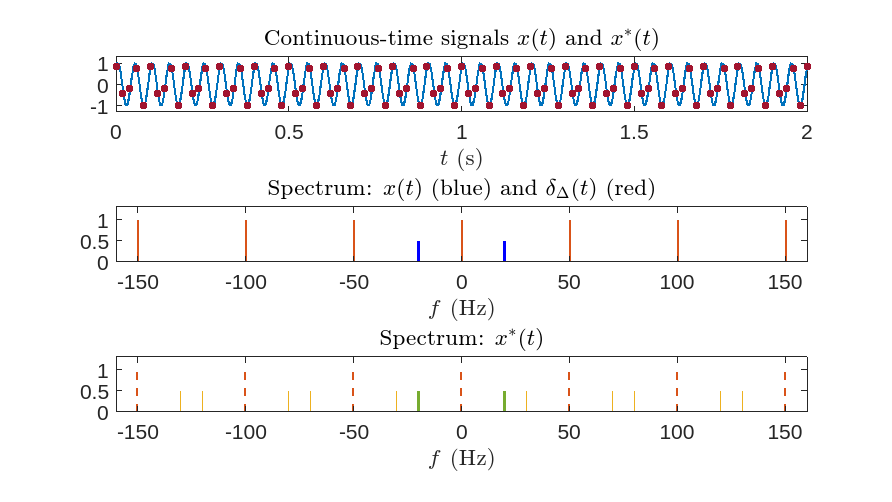

clear 
 

colorset = myPlotColorSet;  % The function creates an array of RGB triplets, 
                            % defining the colors to use when drawing 
                            % 2D line plots. 
                            % Each row of "colorset" is an RGB triplet.


fs = 50;                    % sampling frequency [Hz]
nCT = 100;                  % oversampling factor 
                            % (to plot the continuous-time signals as a smooth curve)
fsCT = fs*nCT;              % increased sampling frequency to plot the continuous-time signals
T = 2;                      % length of the interval to make the plots [s]
phi = pi/3;                 % set the phase of the continuous-time signal

% -- create signals to plot ---------------------------------------------
NDT = T*fs;                 % number of discrete-time points in interval 
                            % the effective samples
tDT = (0:NDT+1)*T/NDT;      % sampling time instants

NCT = T*fsCT;               % number of discrete-time points in interval 
                            % to plot the continuous-time signals as a smooth curve
tCT = (0:NCT+1)*T/NCT;      % the time instants used to evaluate and plot 
                            % the continuous-time signal as a smooth curve


f=20;  % set the frequency of the sine signal


sinCT=sin(2*pi*f*tCT+phi);    % continuous-time signal plot
sinDT=sin(2*pi*f*tDT+phi);    % discrete-time signal plot
% ---------------------------------------------------------------------------

% ---- spectrum of Dirac impulse train --------------------- 
fPlot =( -3.2*fs:3.2*fs);            % spectral lines to be plotted
FDiracTrain = zeros(size(fPlot));
FDiracTrain(rem(fPlot,fs)==0) = 1;    % Fourier transform of Dirac train
fDiracTrain = fPlot(rem(fPlot,fs)==0);% frequencies of the FDiracComb

% spectrum of discrete sine
fDsine=[fDiracTrain'-f fDiracTrain'+f]';

% ------ plotting continuous-time, sampled-time signals and spectra ------
figure('Units','normalized', 'Position',[0.1, 0.1, 0.75, 0.75]);

% -- the continuous-time and the sampled time signals ---
subplot(3,1,1)
plot(tCT,sinCT,'Color', colorset(1,:),'LineStyle','-', 'LineWidth', 1.5);
hold on;
plot(tDT,sinDT, 'Color', colorset(7,:),'LineStyle','none', 'Marker','.', ...
       'MarkerSize', 20, 'MarkerFaceColor','auto');
xlabel('$t$ (s)','interpreter','latex')
title('Continuous-time signals $x(t)$ and $x^{*}(t)$','interpreter','latex')
axis([0,2,-1.3,1.3])
set(gca, 'FontSize', 16);

% --- the amplitude of the Fourier transform --------------------
% for the continuous-time signal and for the Dirac impulse train
subplot(3,1,2)
stem(fPlot,FDiracTrain,'Color',colorset(2,:) ,'LineWidth',1.5 , 'marker','none');
hold on
stem([-f f],[0.5 0.5],'b','marker','none','linewidth',2),hold off
axis([-3.2*fs 3.2*fs 0 1.3])
title('Spectrum: $x(t)$ (blue) and $\delta_{\Delta}(t)$ (red)','interpreter','latex')
xlabel('$f$ (Hz)','interpreter','latex')
set(gca, 'FontSize', 16);

% --- the amplitude of the Fourier transform --------------------
% for the starred signal and for the Dirac impulse train
subplot(3,1,3)
stem(fPlot,FDiracTrain,'Color',colorset(2,:) ,'LineWidth',1.5 ,...
    'LineStyle', '--','marker','none'); % one more time the Dirac train spectrum
hold on
stem(fDsine,0.5*ones(size(fDsine)),'Color',colorset(3,:) ,'LineWidth',1.0 ,...
    'LineStyle', '-','marker','none'); % the multiplated copies of the spectrum

% the starred spectrum components in the so-called primary strip
stem([-f f],[0.5 0.5],'Color',colorset(5,:) ,'LineWidth',2.5 ,...
    'LineStyle', '-','marker','none');
axis([-3.2*fs 3.2*fs 0 1.3])
title('Spectrum: $x^{*}(t)$','interpreter','latex');
xlabel('$f$ (Hz)','interpreter','latex');
set(gca, 'FontSize', 16);

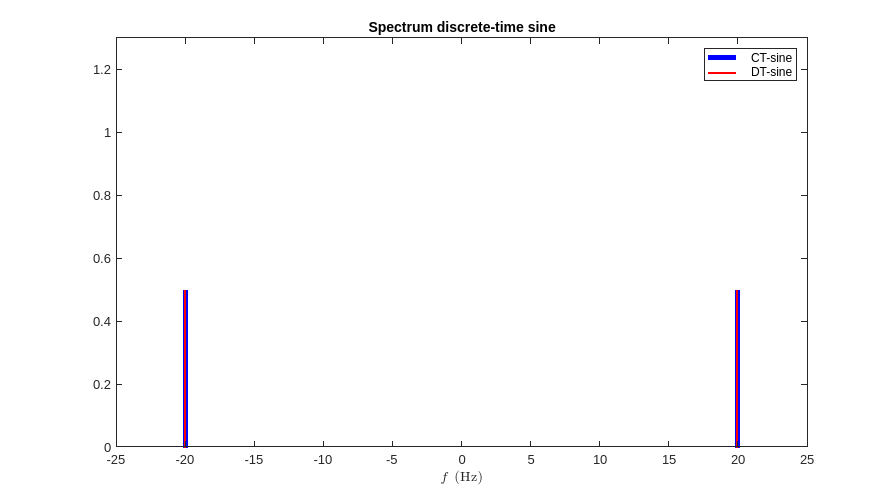

% scaled spectrum of the discrete-time signal vs continuous-time signal
% spectrum
figure('Units','normalized', 'Position',[0.1, 0.1, 0.75, 0.75]);

stem([-f f],[0.5 0.5],'b','marker','none','linewidth',3.5);
hold on
stem(fDsine,0.5*ones(size(fDsine)),'r','marker','none','linewidth',1.5);
hold off
axis([-0.5*fs 0.5*fs 0 1.3])
title('Spectrum discrete-time sine')
xlabel('$f$ (Hz)','interpreter','latex')
legend('CT-sine','DT-sine')

#### **Conclusion**

A discrete-time signal $x_d(k)=x(k \Delta)$ that is obtained by sampling a continuous-time signal $x(t) $ at a sampling frequency $f_s=1/\Delta$(or, equivalently, at the sampling angular frequency $\Omega_s=2\pi/\Delta$) can represent this signal provided that $x(t)$ is a bandlimited signal, i.e.

 $x(t) = \displaystyle\sum_{k=1}^{k= N} \alpha_{k} \sin\left( \Omega_k t + \varphi_k \right)\; ,\quad \Omega_k \le \Omega_{\text{B}} \quad \forall k$, 

or 


$$x(t) = \int_{0}^{\Omega_{\text{B}}}\, \alpha(\Omega) \sin\left[\Omega t + \varphi(\Omega)  \right] \, d \Omega\;,\quad \Omega \in \left[0\;,\quad  \Omega_{\text{B}} \right]$$


and that

 $\displaystyle \frac{\Omega}{2} > \Omega_{\text{B}} \quad \Longleftrightarrow \quad \displaystyle \frac{f_s}{2} >f_{\text{B}}$.  

For a band-limited signal, the spectrum $X_d(f)$ of the sampled signal $x_d(k)=x(k \Delta)$ equals the spectrum $X(f)$ of the continuous-time signal $x(t)$ (second figure in the exercise) in the frequency band $[-f_s/2,f_s/2]$ and we know that the spectrum of the continuous-time signal $X(f)$ is zero outside that band. So we know the full spectrum $X(f)$ of $x(t)$, starting from the spectrum $X_d(f)$of $x_d(k)$.  

If the sampling condition $f_s/2>f_{\text{B}}$ is not respected, aliased frequency components pop-up in the frequency band $[-f_s/2,f_s/2]$ and the user can not determine if the spectrum $X_d(f)$ of the discrete-time signal plotted in the second figure is that of the original continuous-time signal or not. 

This observation leads us directly to the Theorem of Shannon (Oppenheim, Shafer, & Buck, 1998):

*Theorem of Shannon: A necessary and sufficient condition to sample without loss of information a band-limited signal * *with maximum frequency *$f_{\text{B}}$* is that the sampling frequency *$f_s > 2f_{\text{B}}$*.*

## User Guidelines: Sampling in Practice, Aliasing & Anti-Aliasing Filters

In this section we illustrate how to set the user choices when sampling a signal $x(t)$. Following the Theorem of Shannon, the signal should be band-limited, i.e. if

 $x(t) = \displaystyle\sum_{k=1}^{k= N} \alpha_{k} \sin\left( \Omega_k t + \varphi_k \right)\; ,\quad \Omega_k \le \Omega_{\text{B}} \quad \forall k \quad \Longleftrightarrow \quad x(t) = \displaystyle\sum_{k=1}^{k= N} \alpha_{k} \sin\left( 2 \pi f_k t + \varphi_k \right)\; ,\quad f_k \le f_{\text{B}} \quad \forall k $, 

or 


$$x(t) = \int_{0}^{\Omega_{\text{B}}}\, \alpha(\Omega) \sin\left[\Omega t + \varphi(\Omega)  \right] \, d \Omega\;,\quad \Omega \in \left[0\;,\quad  \Omega_{\text{B}} \right] \quad \Longleftrightarrow \quad x(t) = \int_{0}^{f_{\text{B}}}\, 2\pi\,\alpha(f) \sin\left[2 \pi f t + \varphi(f)  \right] \, d f\;,\quad f \in \left[0\;,\quad  f_{\text{B}} \right] $$


Moreover,  the highest frequency $f_{\text{B}}$ should be below half the sampling frequency $f_{\text{B}}<f_s/2$.

Band-limited signals are a theoretical concept, in practice the Shannon condition is mostly not met. In order to keep the aliasing error under control **the user should define the frequency band of interest and add an anti-alias filter** to the measurement channel:

#### *Frequency band of interest * 

This is the frequency band $[-f_I,f_I]$ that will be used during the further processing of the signals. The behavior of the signal outside this frequency band is not relevant for the user. For example, for audio applications the frequency band of interest could be $|f|<20$ kHz. 

#### *Anti-alias (AA) filter*

This is a low-pass filter that attenuates the signal part that is outside the frequency band of interest. A part of this power will disturb the sampled signal in the frequency band of interest (aliasing), and by reducing it to an acceptable level we keep the alias errors below a user defined value. The frequency characteristic of the AA-filter consists of three parts:

- *The passband* of the AA-filter $[0,f_{LP}]$. In this frequency band the signal passes through the filter with only little distortions. The user should specify the acceptable amplitude and phase distortion in the pass-band.  

- *The stopband* of the filter $[f_S, \infty]$: In this frequency band the attenuation of the signal is above a user defined value, for example $A=40$ dB (a factor 100). $f_S$ is the stopband frequency of the filter. 

- *The transition-band* $[f_{LP},f_S]$: This frequency band is needed to be able to realize the filter. In this band, the frequency characteristic moves from the passband specifications to the stopband specifications. *The complexity of the AA-filter* grows when the requested attenuation $A$ in the stopband is increased, when the relative width $f_S/f_{LP}$ of the transition-band is reduced, and when the distortions in the passband are reduced.

#### *Design of the AA-filter and choice of the sampling frequency*

Both choices are linked: the closer the sampling frequency $f_s$  will be to the frequency band of interest $f_I$, the harder it becomes to design a good AA-filter that meets the user specifications. 

- The first choice is the selection of the frequency band of interest $[-f_I,f_I].$ This is a user choice and is set by the intended application. 

- Next, the sampling frequency is selected $f_s>2f_I$. This is the minimum requirement. In practice it should be even larger in order to be able to design an AA-filter and to decrease its complexity. 

- The band-pass of the AA-filter should cover the frequency band of interest: $f_{LP} \ge f_I$. 

- The stop-band frequency $f_S<f_s-f_I$. The latter frequency $f_s-f_I$ is the first alias component that will disturb the frequency band of interest. It should be in the stop-band of the AA-filter so that it is guaranteed to be below the acceptable level set by the user.  This choice guarantees that the aliased part of the signal that is disturbing the frequency band of interest is attenuated with $A$ dB. 

***Remark***: The perfect AA-filter has a zero ripple (amplitude distortion) and a zero phase in the pass-band. In practice this is not realizable. The amplitude will always vary and the phase will be different from zero. The zero-phase condition can be relaxed to a linear phase. In that case, the ideal filter will delay the signal. In many applications, such a delay can be tolerated. However, in critical online applications, for example digital control, the delay can destabilize the control loop. For that reason, AA-filters are often avoided in control applications while they should be a standard component in a good data-acquisition channel.

### **Simulation**

These ideas are illustrated in the following (discrete-time) simulation of the sampling process. A low-pass random signal $x(t)$ is sampled at a frequency of $f_s=2000$Hz. The user can specify the bandwidth $f_x$ of $x(t)$ and the bandwidth of the AA-filter. We assume that the frequency band of interest is equal to the passband of the AA-filter $f_I=f_{LP}$. The AA-filter is a Butterworth filter of order 5 (a classical LP-filter, with flat amplitude spectrum for frequencies around the null frequency). This choice sets implicitly the value of the stop-band frequency $f_S$.  

We show four plots. In the first plot, the amplitude spectrum $|X(f)|$ of the actual realization of the random signal is shown. In the second plot, the scaled amplitude spectrum $|X^*(f)|$ of $x^*(t)$ is shown. The bold black lines indicate the interval $[-f_s/2,f_s/2]$. In the third plot, we show the first 3 components of the scaled spectrum $|X^*(f)|$ of eq. (1):


$$X^{*}(f) = \mathcal{F} \left\{ x^*(t) \right\} = \mathcal{F}\left\{ x(t) \cdot \delta_{\Delta}(t) \right\} = f_{\text{s}} \, \displaystyle \sum_{k=-\infty}^{k=+\infty} \, X\left( f-k f_{\text{s}} \right)   \, , \quad k \in \mathbb{Z}\,, \quad f_{\text{s}} = \frac{1}{\Delta} $$


for $k=0$ in blue, $k=1$ (red), and $k=-1$(green).The scaling factor $f_s$ is removed in the plot. The plot visualizes the spectrum that is aliased down in the the interval $[-f_s/2,f_s/2]$.

In the last plot we show the same figure but $x(t)$ is passed through the AA-filter before it is sampled. The broken black line shows the amplitude characteristic of the AA-filter. 

- ***Situation 1***: Set $f_x=100$Hz and the bandwidth of the AA-filter $f_{\text{LP}}=800$ Hz. 

- Check the shape of$|X(f)|$ in the first plot.  It shows the low-pass nature of the signal (the spectrum goes to zero for increasing frequencies).

- The scaled spectrum of the equivalent sampled signal $|X^*(f)|$ in the second plot shows the sampling effect. The spectrum is repeated around the multiples of the sampling frequency $f_s=2000$Hz. This created alias errors in the frequency band of interest. 

- The level of the alias errors can be seen in the third plot: the red and green contributions are the aliased components that are added to the blue original spectrum of the signal $x(t)$ that we want to measure. These errors should be below the user specified value. In this case the errors are at the level of -20 dB (10%). 

- In the last plot the same results are shown for the AA-filtered signal. The red lines indicate the passband of the AA-filter. The frequency band of interest should be inside the interval. Observe that the alias errors (red, green) are significantly reduced.  

- The alias errors can be further reduced by lowering the bandwidth of the AA-filter to $f_{\text{LP}}=700$Hz (this will also reduce the frequency band of interest). Check how this choice changes the amplitude characteristic of the AA-filter and reduces the aliasing errors. The latter are now below -40 dB in the frequency band of interest.

- ***Situation 2***: Set $f_x=1000$Hz, keep $f_{\text{LP}}=700$Hz. 

- In the first plot it is seen that $|X(f)|$ slowly decreases for $|f|>1000$ Hz.  

- The spectrum of the equivalent sampled signal $|X^*(f)|$ is flat. This is due to the aliasing as can be seen in the third plot.

- Vary the bandwidth of the AA-filter such that the alias errors in the frequency band of interest are below -50 dB. A bandwidth of $f_{\text{LP}}=500$ Hz meets this constraint.

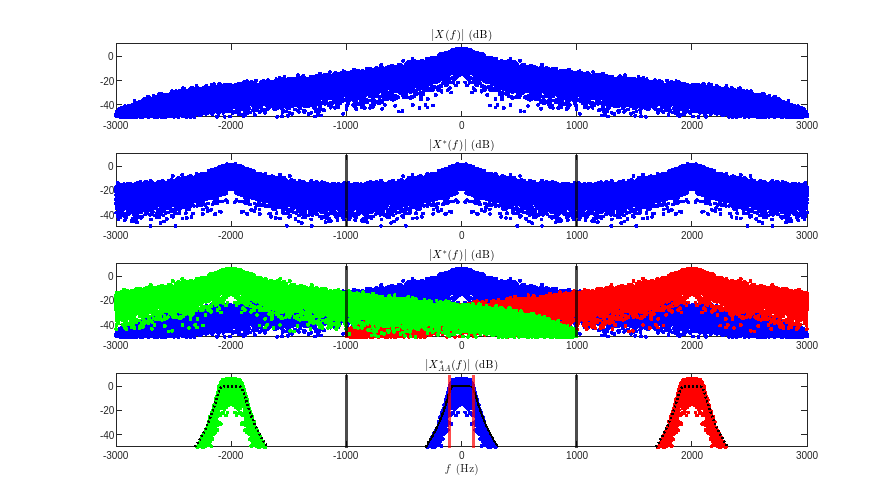

clear 
fs=2000;        % sampling frequency [Hz]
fsCT=fs*3;    % fast sampling to make CT simulation
 
fBW=100;        % bandwidth of the first order colored noise signal
fAA=100; % bandwith of the anti-alias filter
       

N=10000;        % length of the processed data record
NCT=N*fsCT/fs;  % length of the continuous-time data record

% create the generator filter
[bGen,aGen]=butter(1,2*fBW/fsCT);bGen(2)=bGen(2)*1.1;     % first order lowpass filter

% create the AA-filter
[bAA,aAA]=butter(5,2*fAA/fsCT);        % 5th order AA-filter

% generate the CT signal
x=randn(1,NCT);x=[x x];        % CT signal, periodic to avoid leakage errors in analysis
x=filter(bGen,aGen,x);         % lowpass CT  signal
xAA=filter(bAA,aAA,x);         % AA filtered CT signal
uCT=x(NCT+1:end)';                % select 1 period for the analysis
uCTAA=xAA(NCT+1:end)';            % select 1 period for the analysis

% create the sampled signal x^*
utd=zeros(size(uCT));
utdAA=zeros(size(uCT));
n=fsCT/fs;ts=[1:n:NCT];    % sample times 
utd(ts)=uCT(ts);
utdAA(ts)=uCTAA(ts);

% plot of the spectra
UCT=fft(uCT)/sqrt(NCT);UCT=circshift(UCT,NCT/2+1);
UCTAA=fft(uCTAA)/sqrt(NCT);UCTAA=circshift(UCTAA,NCT/2+1);
Utd=fft(utd)/sqrt(length(ts));Utd=circshift(Utd,NCT/2+1);
UtdAA=fft(utdAA)/sqrt(length(ts));UtdAA=circshift(UtdAA,NCT/2+1);
f=[-NCT/2:NCT/2-1]/NCT*fsCT;    % frequency axis
GAA=db(freqz(bAA,aAA,f*2*pi/fsCT));

figure('Units','normalized', 'Position',[0.1, 0.1, 0.75, 0.75]);
subplot(4,1,1)
plot(f,db(UCT),'.b')
axis([-fsCT/2 fsCT/2 -50 10 ])
title('$|X(f)|$ (dB)','interpreter','latex')

subplot(4,1,2)
plot(f,db(Utd),'.b')
xline(-fs/2,'k','linewidth',2);xline(+fs/2,'k','linewidth',2);
axis([-fsCT/2 fsCT/2 -50 10])
title('$|X^*(f)|$ (dB)','interpreter','latex')

subplot(4,1,3)
plot(f,db(UCT),'.b',f+fs,db(UCT),'.r',f-fs,db(UCT),'.g')
xline(-fs/2,'k','linewidth',2);xline(+fs/2,'k','linewidth',2);
axis([-fsCT/2 fsCT/2 -50 10 ])
title('$|X^*(f)|$ (dB)','interpreter','latex')

subplot(4,1,4)
plot(f,db(UCTAA),'.b',f+fs,db(UCTAA),'.r',f-fs,db(UCTAA),'.g');hold on
plot(f,GAA,'k',f+fs,GAA,':k',f-fs,GAA,':k','linewidth',2),hold off
axis([-fsCT/2 fsCT/2 -50 10 ])
xline(-fs/2,'k','linewidth',2);xline(+fs/2,'k','linewidth',2);
xline(-fAA,'r','linewidth',2);xline(+fAA,'r','linewidth',2);
xlabel('$f$ (Hz)','interpreter','latex')
title('$|X^{*}_{AA}(f)|$ (dB)','interpreter','latex')

### Conclusion

Sampling a continuous-time signal creates alias errors because the theorem of Shannon is not met in most practical situations. The alias errors can be controlled during the design of the measurement setup by a careful selection of the frequency band of interest $f_I$, the sampling frequency $f_s$, and the design of the AA-filter. Increasing the sampling frequency $f_s$ and reducing the frequency band of interest $f_I$ (or in general reducing the ratio $f_I/f_s$) relaxes the design criteria of the AA-filter. 

The reader should keep in mind that a perfect AA-filter does not exist. Even in the passband of the filter, amplitude and phase distortions will occur. In the best case (linear phase distortion), the AA-filter still adds a delay in the measurement channel. In some applications (for example in control design) this might be unacceptable. 

Measuring without AA-filter can only be done if a preliminary analysis of the spectrum of the continuous-time signal $u(t)$ shows that it is safe to do so.

The AA-filter is an analogue filter that operates on the continuous-time signal. Once the sampling is done, it is too late to try to reduce the alias error by adding a digital filter because the aliasing occurs during the sampling.

## References

Phillips, C. L., Nagle, H. T., & Chakrabortty, A. *Digital Control System Analysis and Design*. Pearson, 2015

Oppenheim, A.V.,  Shafer, R. W.,  & Buck, J. R., *Discrete-Time Signal Processing, Prentice Hall, *1998